syms t v beta eta;
prob(t,v,beta,eta) = beta/eta*((v+t)/eta)^(beta-1)*exp((v/eta)^beta-((v+t)/eta)^beta)

$$prob(t, v, beta, eta) = \frac{\beta \,{\mathrm{e}}^{{\left(\frac{v}{\eta }\right)}^{\beta }-{\left(\frac{t+v}{\eta }\right)}^{\beta }}\,{\left(\frac{t+v}{\eta }\right)}^{\beta -1}}{\eta }$$

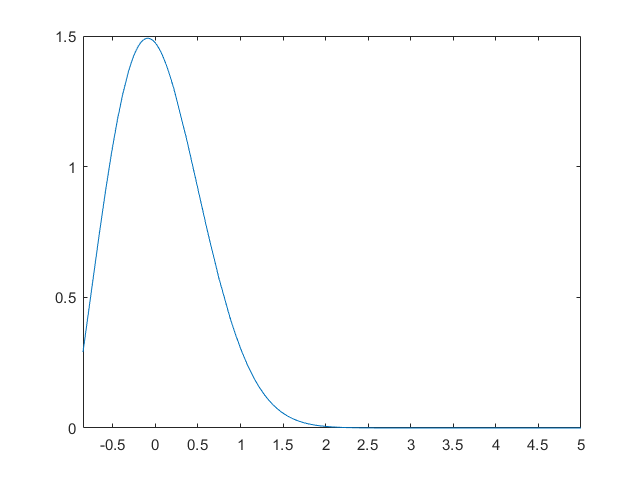

figure
fplot(prob(t,1,2.2,1.2))

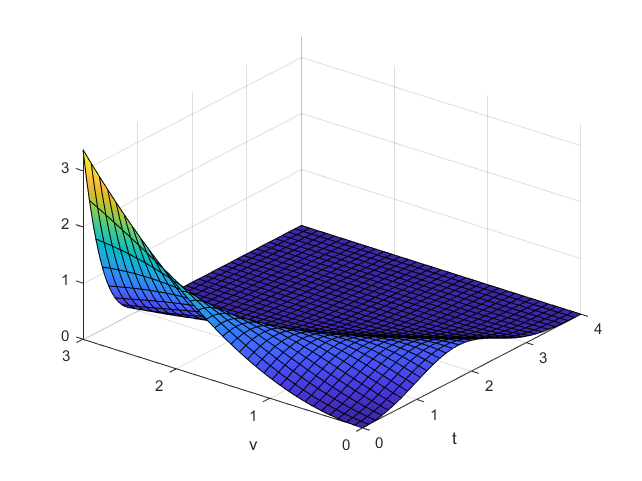

%plot pdf
figure
fsurf(prob(t,v,3,2),[0 4 0 3])
view([-52.02 37.30])
xlabel t
ylabel v

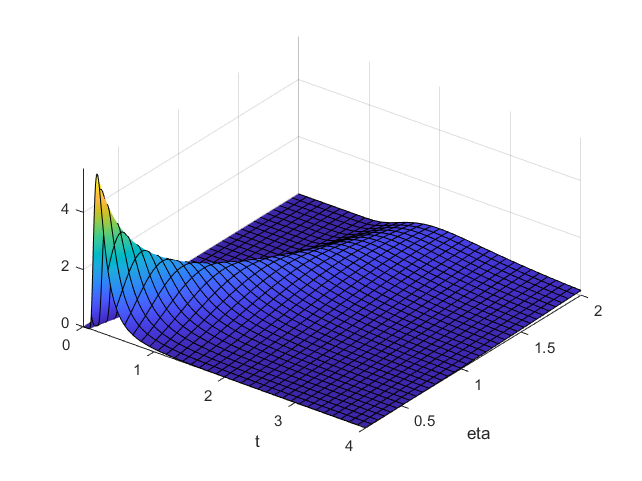

%plot pdf
figure
fsurf(prob(t,0,3,eta),[0 4 0.2 2])
view([-52.02 37.30])
xlabel t
ylabel eta

random_RAM = [];
a_r = 0.8

a_r = 0.8000

a_p = 0.3

a_p = 0.3000

v_ = 0;
for n = (1:40)
    CM = true;
    maker = PDFsampler(double(prob(0:0.1:5,v_,3,2)),51);
    random = maker.nextRandom;
    RAM_scaler = rand()*0.1;
    if(random > RAM_scaler)
        random = RAM_scaler;
        CM = false;
    end
    random_RAM = [random_RAM;n CM random];
    v = v + CM*a_r*random + (1-CM)*a_p*random;
end